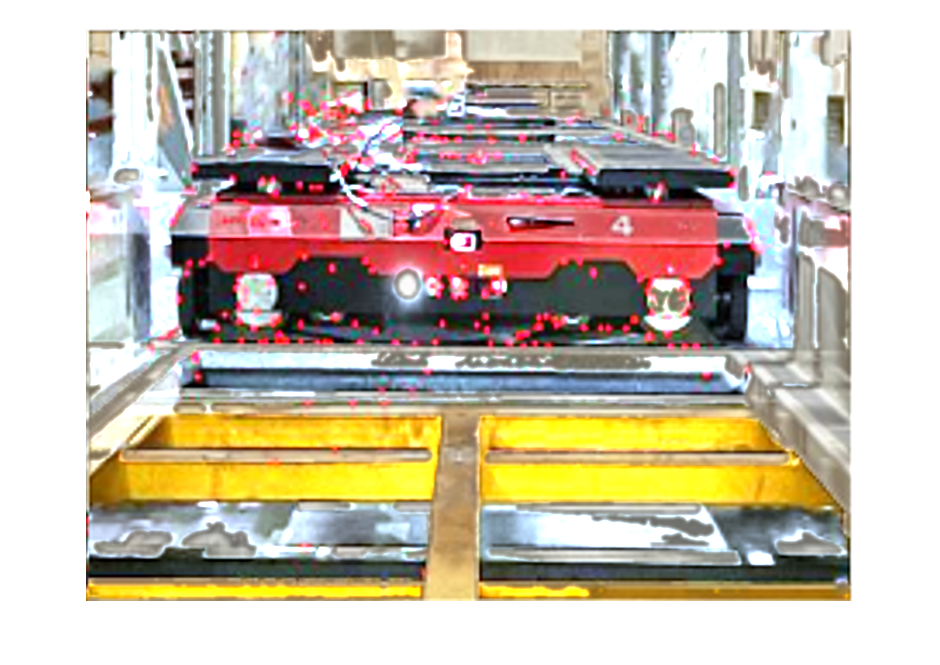

clear all;
img = imread('methodLight.png');
imshow(img);

a1=mean2(img);

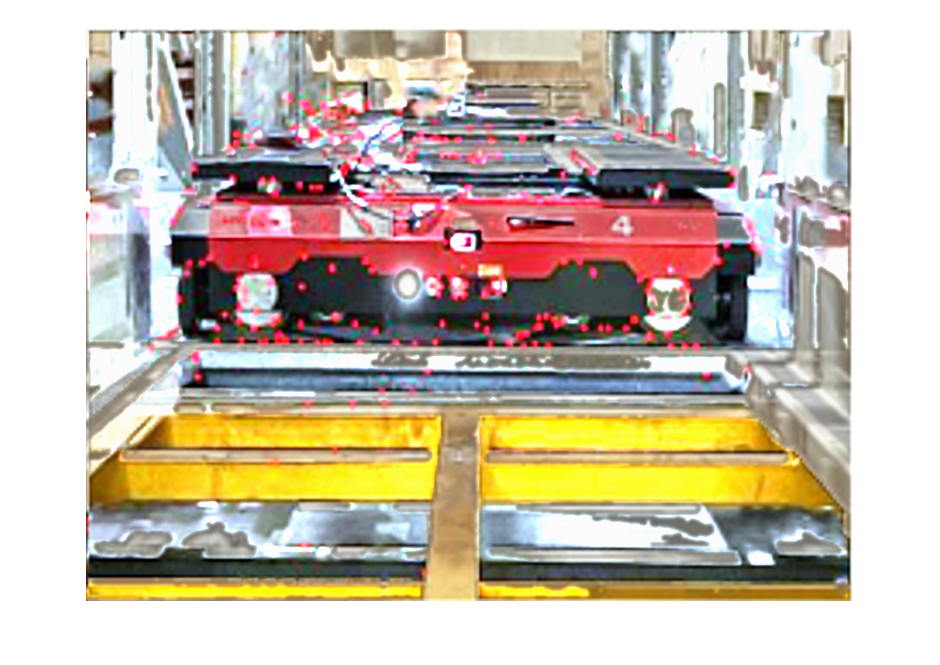


% hsv=rgb2hsv(img);
% h=hsv(:,:,1);
% s=hsv(:,:,2);
% v=hsv(:,:,3);
% v=histeq(v);   %提升图像对比度
% % imhist(v);
% hsv(:,:,1)=h;
% hsv(:,:,2)=s;
% hsv(:,:,3)=v;
% rgb1=hsv2rgb(hsv);
% imshow(rgb1)

[m,n,k] = size(img);   %读取图片大小
hsv = rgb2hsv(img);     %颜色空间转换
H = hsv(:,:,1); % 色调
S = hsv(:,:,2); % 饱和度
V = hsv(:,:,3); % 亮度

for i = 1:m    %遍历每一个像素点，可以根据需要选择自己需要处理的区域
for j = 1: n
hsv(i,j,3) =0.99* hsv(i,j,3);   %1.5位需要增强的倍数，可以根据图片情况动态调整
end
end

rgb2 = hsv2rgb(hsv); %转为RGB，进行显示
imshow(rgb2);


a2=mean2(rgb2);
